# Dynamique

## Modèle

### Bistable seul

Nous modéliserons le bistable par un ressort de compression et en négligeant les frottements.

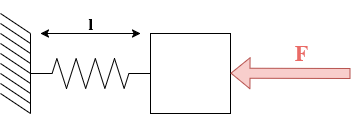

Avec :


$$\begin{array}{l}
F=k_c *l\;\\
U_c =\frac{1}{2}*k_c *l^2 
\end{array}$$


k_c = 0.8;
l = 40*10^-3;
F = k_c*l

F = 0.0320

### Mécanisme seul

Pour l'étude du mécanisme, nous ferons une étude comparative de deux hypothèses différentes de modélisation des liaisons :

- Liaisons parfaites

- Ressorts de torsion

Dans les deux cas, nous négligerons les frottements avec le sol.

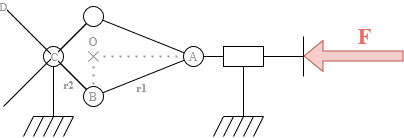

#### Liaisons parfaites

Sous cette hypothèse, la force est transmise au sein du mécanisme par des relations de leviers


$$C_B =\frac{F_A }{2}*r_1$$



$$F_D =\frac{C_B }{r_2 }$$


r1 = 191*10^-3;
r2 = 41*10^-3;

#### Ressorts de torsion

Sous cette hypothèse, les liaisons pivots sont modélisées par des ressorts de torsions, afin de prendre en compte les frottements ainsi que les erreurs d'impressions.


$$\tau =-k_t *\theta$$



$$U_t =\frac{1}{2}*k_t *\theta^2$$


k_t = 0.01;

L'étude de la géométrie du modèle nous donne les valeurs de déplacement angulaires $\theta$.

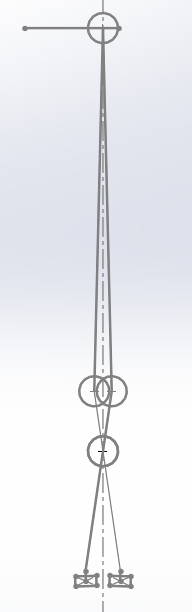 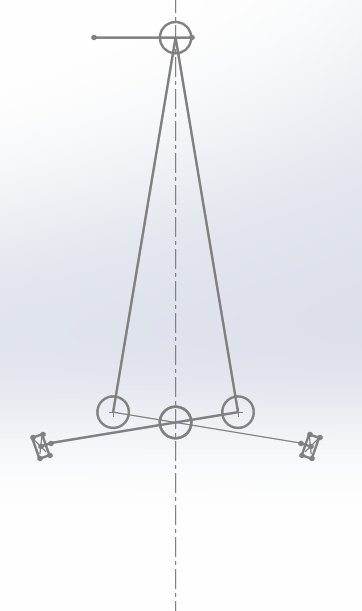

theta_A = deg2rad(7.5);
theta_B = deg2rad(70);
theta_C = deg2rad(77);

### Hélice et moteur seuls

Dans ce cas, nous modéliserons uniquement les forces de frottements entre le système {moteur, hélice, support imprimé en 3D} et le sol. Nous approximerons un frottement sec, plastique-bois.

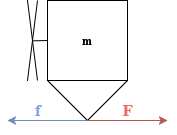


$$\begin{array}{l}
t=0:f_s =\mu_s *N\\
t>0:f_c =\mu_c *N
\end{array}$$


mu_s = 0.4;
mu_c = 0.3;
m_m = 38*10^-3; % en kg
g = 9.81;
N = m_m*g;
f_s = mu_s*N

f_s = 0.1491

f_c = mu_c*N

f_c = 0.1118

## Équations

### t = 0

À $t=0$, nous considérerons que les ressorts sont au repos et donc que, pour de petits déplacements, nos liaisons sont parfaites. Nous considérerons également des forces de frottement sec statique au niveau des moteurs.

Nous rappelons les équations précédentes :

$C_B =\frac{F_A }{2}*r_1$ ; $F_D =\frac{C_B }{r_2 }$ ; $f_s =\mu_s *N$

en posant $f_s =F_D$ Nous obtenons :


$$f_s =\frac{C_B }{r_2 }=\frac{F_A }{2}*\frac{r_1 }{r_2 }$$


donc :


$$\frac{F}{2}=\;F_A =2\;f_s *\left(\frac{r_2 }{r_1 }\right)$$


Avec $F$ la force nécessaire pour mettre en mouvement le mécanisme.

F = 4*f_s*(r2/r1)

F = 0.1280

### t > 0

À $t>0$ nous considérerons les liaisons pivots comme ayant le comportement de ressorts de torsion. Nous considérerons également des forces de frottements secs cinétiques au niveau des moteurs. Ici l'objectif est de donner assez d'énergie au mécanisme pour qu'il change d'état stable.


$$U_c =\frac{1}{2}*k_t *\theta^2$$



$$U_t =\frac{1}{2}*k_t *\theta^2$$


Nous noterons la masse totale du robot m en kg, la durée du choc delta_t en s.

m = 1;
CD = 65*10^-3;
delta_t = 0.1;

U1 = 0.5*k_c*l^2

U1 = 6.4000e-04

U2 = 0.5*k_t*theta_A^2

U2 = 8.5674e-05

U3 = 0.5*k_t*theta_B^2

U3 = 0.0075

U4 = 0.5*k_t*theta_C^2

U4 = 0.0090

U5 = mu_c*m_m*g*theta_C*CD

U5 = 0.0098

En émettant l'hypothèse de la conservation de l'énergie dans un système, nous calculons l'énergie $U_s$ nécessaire avant le choc afin d'actionner notre bistable :


$$U_s =\frac{1}{2}m*v^2 =\sum U_i$$


donc :


$$v=\sqrt{\frac{2}{m}*\sum U_i }$$


U_s = U1+U2+U3+U4+U5; %-U_f;
v = sqrt(U_s*2/m)

v = 0.2323

f = m * v/delta_t

f = 2.3233


f > F

ans = logical
   1
